assert(endsWith(pwd, "\ferromagnetic metal plate in frequency domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear

## Distributed Current Source

#### Coil

Coil.num = 1;
Coil.inner_radius = 3.75e-3; % (m)
Coil.outer_radius = 6.00e-3; % (m)
Coil.length       = 4.00e-3; % (m)

Coil.wire_diameter = 0.35e-3; % (m)
Coil.N_turns = 60;
Coil.conductivity = 6e7; % (S/m)

Coil_pos = [0, 0, 4e-3]; % (m)
Coil = SetPositionRotation3D(Coil, Coil_pos, [1,0,0], deg2rad(0));
clear Coil_pos

#### Sensor

Sensor.num = 20;
Sensor.side_length = 1e-3;

Sensor_pos = [
    linspace(-20e-3,20e-3,Sensor.num); 
    0      * ones(1,Sensor.num); 
    1.5e-3 * ones(1,Sensor.num)       ];
Sensor = SetPositionRotation3D(Sensor, Sensor_pos');
clear Sensor_pos

#### Model

plate.l = 40e-3; % (m)
plate.h = 3e-3;  % (m)
plate.n_l = 25; % number of elements in x and y direction
plate.n_z = 3;  % number of elements in z direction

delta = 1 / sqrt(pi * 500 * 1.45e6 * 4*pi*1e-7 * 100);

x = linspace(-plate.l/2, plate.l/2, plate.n_l+1);
y = x;
z = delta * log(1 + (-plate.n_z:0)/plate.n_z * (1-exp(-plate.h/delta)));

Model = BuildModel3D('Cuboid', x,y,z);

build model took 0.08 seconds


clear plate x y z

Model.conductivity = 1.45e6 * ones(1,Model.num_elems); % (S/m)
Model.relative_permittivity = 1 * ones(1,Model.num_elems); % (1)
Model.relative_permeability = 100 * ones(1,Model.num_elems); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation3D(Model, Coil, Sensor);

build governing equation took 12.67 seconds


#### Solve in frequency domain

V_E = readmatrix('FEA_data/V_E.csv', 'CommentStyle','%');
V_E = V_E(4);
Coil.frequency_domain.excitation = {"Voltage" V_E}; % (V)
clear V_E

Coil.frequency_domain.excitation = {"Current" 1}; % (A)

Coil.frequency_domain.frequency = 500; % (Hz)
[Model, Coil, Sensor] = SolveFrequencyDomain3D(GoverningEquation, Model, Coil, Sensor);

solve in frequency domain took 8.05 seconds


#### Plot world

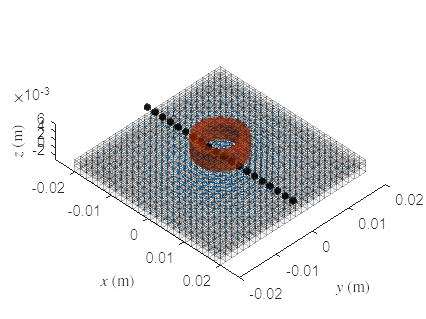

r = Model.elems_center;
J = real(Model.frequency_domain.J);

figure
PlotWorld3D(Model, Coil, Sensor)
quiver3(r(1,:),r(2,:),r(3,:), J(1,:),J(2,:),J(3,:))


clear r J

## Compare with FEA

#### Current density

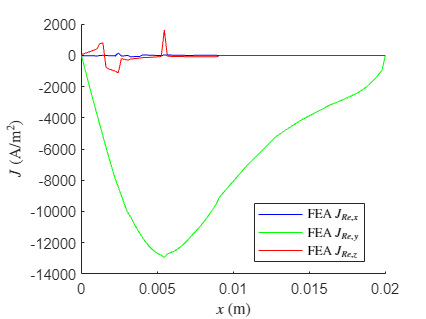

data = readmatrix('FEA_data/J.txt', 'CommentStyle','%');
FEA.x = data(:,1);
FEA.J_x = data(:,4);
FEA.J_y = data(:,5);
FEA.J_z = data(:,6);
clear data

mask = Model.elems_center(1,:) >= 0 & Model.elems_center(2,:) == 0 & abs(Model.elems_center(3,:) - -1.5e-3) < 1e-6;

figure
hold on
plot(FEA.x, real(FEA.J_x), 'b-', 'DisplayName','FEA $J_{Re,x}$')
plot(FEA.x, real(FEA.J_y), 'g-', 'DisplayName','FEA $J_{Re,y}$')
plot(FEA.x, real(FEA.J_z), 'r-', 'DisplayName','FEA $J_{Re,z}$')
plot(Model.elems_center(1,mask), real(Model.frequency_domain.J(1,mask)), 'bx', 'DisplayName','DCS $J_{Re,x}$')
plot(Model.elems_center(1,mask), real(Model.frequency_domain.J(2,mask)), 'gx', 'DisplayName','DCS $J_{Re,y}$')
plot(Model.elems_center(1,mask), real(Model.frequency_domain.J(3,mask)), 'rx', 'DisplayName','DCS $J_{Re,z}$')
legend('show', 'Location','best', 'Interpreter','latex')
xlabel("$x$ (m)", 'Interpreter','latex')
ylabel("$J$ (A/m$^2$)", 'Interpreter','latex')

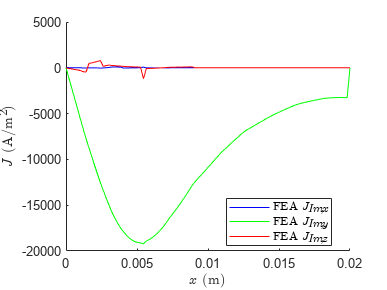


figure
hold on
plot(FEA.x, imag(FEA.J_x), 'b-', 'DisplayName','FEA $J_{Im,x}$')
plot(FEA.x, imag(FEA.J_y), 'g-', 'DisplayName','FEA $J_{Im,y}$')
plot(FEA.x, imag(FEA.J_z), 'r-', 'DisplayName','FEA $J_{Im,z}$')
plot(Model.elems_center(1,mask), imag(Model.frequency_domain.J(1,mask)), 'bx', 'DisplayName','DCS $J_{Im,x}$')
plot(Model.elems_center(1,mask), imag(Model.frequency_domain.J(2,mask)), 'gx', 'DisplayName','DCS $J_{Im,y}$')
plot(Model.elems_center(1,mask), imag(Model.frequency_domain.J(3,mask)), 'rx', 'DisplayName','DCS $J_{Im,z}$')
legend('show', 'Location','best', 'Interpreter','latex')
xlabel("$x$ (m)", 'Interpreter','latex')
ylabel("$J$ (A/m$^2$)", 'Interpreter','latex')


clear mask

#### Magnetic flux density

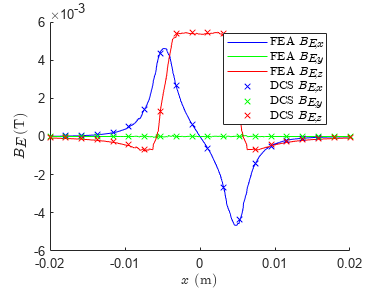

data = readmatrix('FEA_data/B.txt', 'CommentStyle','%');
FEA.x     = data(:,1);
FEA.B_E_x = data(:,7);
FEA.B_E_y = data(:,8);
FEA.B_E_z = data(:,9);
FEA.B_C_x = data(:,4) - FEA.B_E_x;
FEA.B_C_y = data(:,5) - FEA.B_E_y;
FEA.B_C_z = data(:,6) - FEA.B_E_z;
clear data

figure
hold on
plot(FEA.x, real(FEA.B_E_x), 'b-', 'DisplayName','FEA $B_{E,x}$')
plot(FEA.x, real(FEA.B_E_y), 'g-', 'DisplayName','FEA $B_{E,y}$')
plot(FEA.x, real(FEA.B_E_z), 'r-', 'DisplayName','FEA $B_{E,z}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_E(1,:)), 'bx', 'DisplayName','DCS $B_{E,x}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_E(2,:)), 'gx' ,'DisplayName','DCS $B_{E,y}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_E(3,:)), 'rx' ,'DisplayName','DCS $B_{E,z}$')
legend('show', 'Location','best', 'Interpreter','latex')
xlabel("$x$ (m)", 'Interpreter','latex')
ylabel("$B_E$ (T)", 'Interpreter','latex')

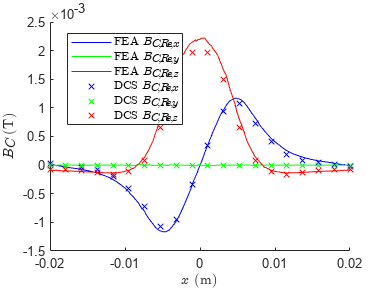


figure
hold on
plot(FEA.x, real(FEA.B_C_x), 'b-', 'DisplayName','FEA $B_{C,Re,x}$')
plot(FEA.x, real(FEA.B_C_y), 'g-', 'DisplayName','FEA $B_{C,Re,y}$')
plot(FEA.x, real(FEA.B_C_z), 'r-', 'DisplayName','FEA $B_{C,Re,z}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_C(1,:)), 'bx', 'DisplayName','DCS $B_{C,Re,x}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_C(2,:)), 'gx' ,'DisplayName','DCS $B_{C,Re,y}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_C(3,:)), 'rx' ,'DisplayName','DCS $B_{C,Re,z}$')
legend('show', 'Location','best', 'Interpreter','latex')
xlabel("$x$ (m)", 'Interpreter','latex')
ylabel("$B_C$ (T)", 'Interpreter','latex')

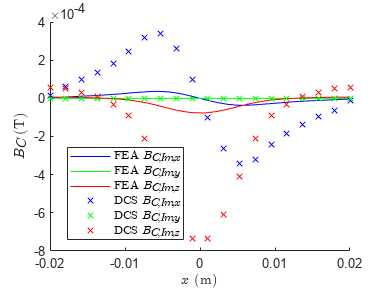


figure
hold on
plot(FEA.x, imag(FEA.B_C_x), 'b-', 'DisplayName','FEA $B_{C,Im,x}$')
plot(FEA.x, imag(FEA.B_C_y), 'g-', 'DisplayName','FEA $B_{C,Im,y}$')
plot(FEA.x, imag(FEA.B_C_z), 'r-', 'DisplayName','FEA $B_{C,Im,z}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_C(1,:)), 'bx', 'DisplayName','DCS $B_{C,Im,x}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_C(2,:)), 'gx' ,'DisplayName','DCS $B_{C,Im,y}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_C(3,:)), 'rx' ,'DisplayName','DCS $B_{C,Im,z}$')
legend('show', 'Location','best', 'Interpreter','latex')
xlabel("$x$ (m)", 'Interpreter','latex')
ylabel("$B_C$ (T)", 'Interpreter','latex')